disp('Articulated')

Articulated



a1 = 5;
a2 = 7;
a3 = 4;


H0_1 = Link([0,a1,0,pi/2,0]);
H0_1.qlim = pi/180*[-90 90];

H1_2 = Link([0,0,a2,0,0]);
H1_2.qlim = pi/180*[-90 90];

H2_3 = Link([0,0,a3,0,0]);
H2_3.qlim = pi/180*[-90 90];

Articulated = SerialLink([H0_1 H1_2 H2_3], 'name', 'Articulated')

 
Articulated = 
 
Articulated:: 3 axis, RRR, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          5|          0|     1.5708|          0|
|  2|         q2|          0|          7|          0|          0|
|  3|         q3|          0|          4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


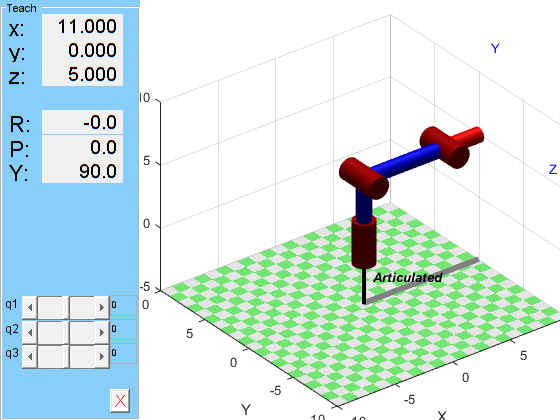

Articulated.plot([0 0 0], 'workspace',[-10 10 -10 10 -5 10])
Articulated.teach